# Lab 5 

## Set Global Parameters 

% Parameter values for hodgkin-huxley model 

Gl = 3.0e-8;    % leak conductance in Siemens 
Gna = 1.2e-5;   % maximum sodium conductance in Siemens
Gk = 3.6e-5;   % maximum delayed rectifier current in Siemens 
Ena = 45e-3;   % sodium reversal potential in V
Ek = -82e-3;   % potassium reversal potential in V
El = -60e-3;   % leak reversal potential in V
Cm = 1.e-10;   % membrane capacitance in F

## Question 1 

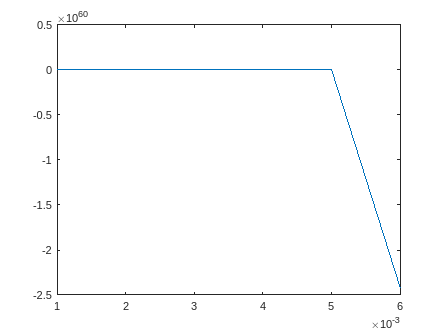

% Initialize Variable Vectors 
tspan = 35;           % time length of stimulation 
dt = 0.001;            % time step for euler method
loop = ceil(tspan/dt); 
t = (1:loop)*dt; 

V = zeros(1,loop);
m = zeros(1,loop);
h = zeros(1,loop);
n = zeros(1,loop);

% Initial Conditions  
V(1) = -70e-3;
m(1) = 0;
h(1) = 0;
n(1) = 0;
Iapp = 0;

% Euler Method 
for i = 2:length(t)
    dVdt = 1/Cm*(Gl*(El -V(i-1))+Gna*m(i-1)^3*h(i-1)*(Ena-V(i-1))+Gk*n(i-1)^4*(Ek-V(i-1))+Iapp);
    V(i) = V(i-1) + dVdt*dt;
    m(i) = m(i-1) + dt*(alphaM(V(i-1))*(1-m(i-1))- betaM(V(i-1))*m(i-1));
    h(i) = h(i-1) + dt*(alphaH(V(i-1))*(1-h(i-1))- betaH(V(i-1))*h(i-1));
    n(i) = n(i-1) + dt*(alphaN(V(i-1))*(1-n(i-1))- betaN(V(i-1))*n(i-1));
end
plot(t,V);

function aM = alphaM(V) % alpha and beta rate functions for gating variables
aM = (10^-5*(-V - 0.045))/(exp(100*(-V -0.045))-1);
end
function bM = betaM(V)
bM = 4e3*exp((-V - 0.070)/0.018);
end
function aH = alphaH(V)
aH = 70*exp(50*(-V-0.070));
end
function bH = betaH(V)
bH = 10e3/(1+exp(100*(-V - 0.040)));
end
function aN = alphaN(V)
aN = (10e4*(-V-0.060))/(exp(100*(-V-0.060)) -1);
end
function bN = betaN(V)
bN = 125*exp((-V-0.070)/0.08);
end